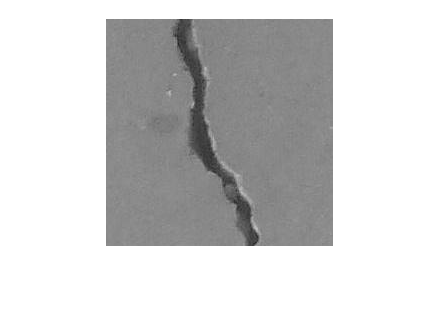

img = im2gray(imread("Data/Concrete Crack Images/00001.jpg"));
imshow(img);

BW = imbinarize(img)

BW = 227×227 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1 

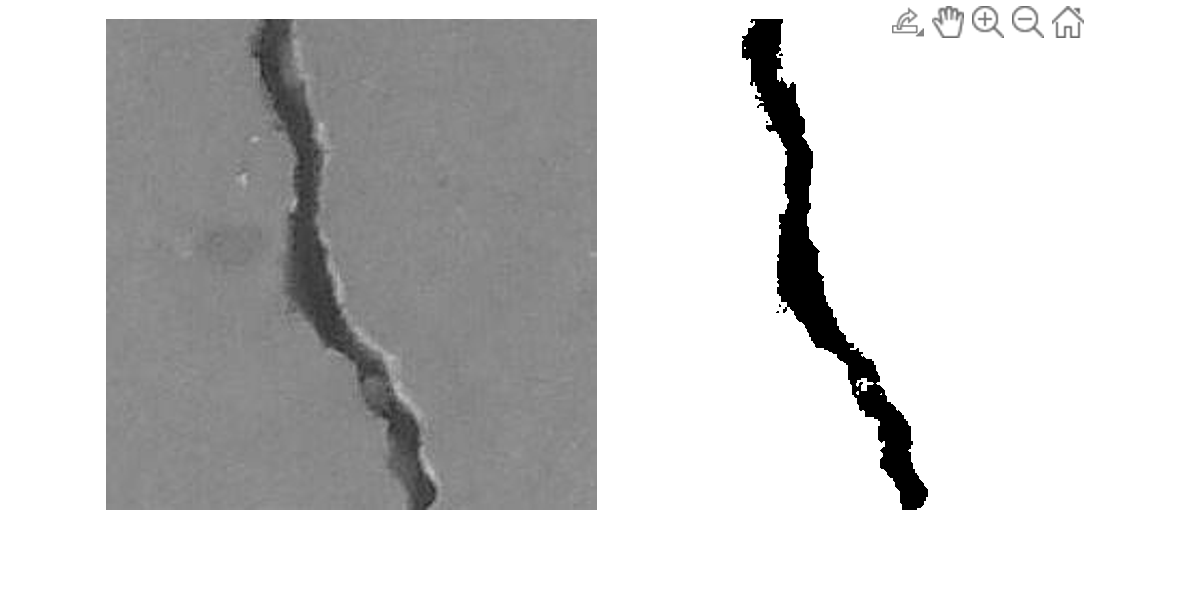

montage({img, BW})

Since we are interested in the crack itself and not the concreate we should use the logical "not" to obtai the inverted section:

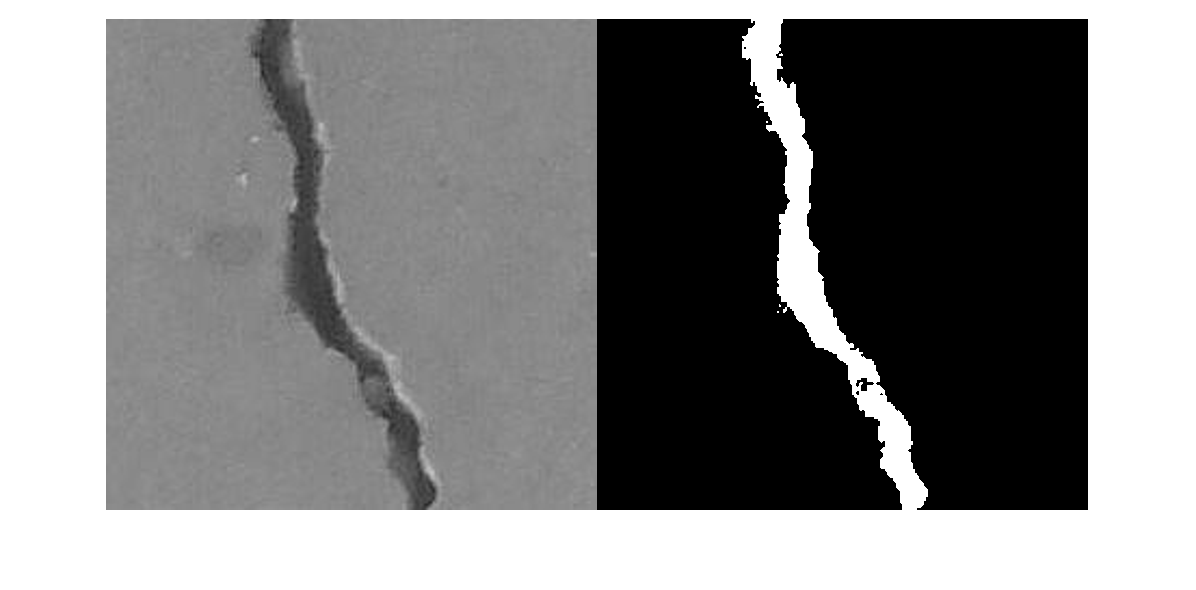

BW = ~BW;
montage({img, BW})

nnz(BW)

ans = 3353

# Obtaining a masked image :

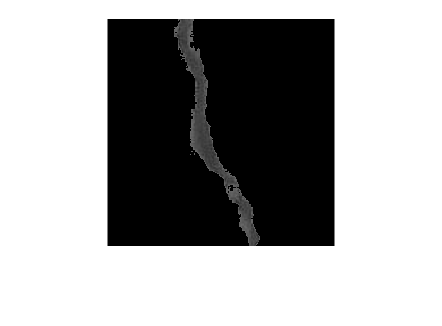

maskedImg = img;
maskedImg(~BW) = 0;
imshow(maskedImg);

The above image is an image where all the pixel points were zero except where the mask was true.

**Applying a threshold slider** to find a threshold manually when the crack in the concrete is too thin :

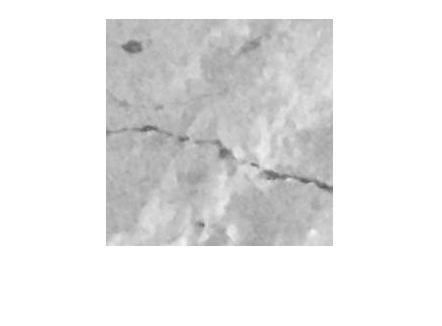

img = im2gray(imread("Data/Concrete Crack Images/00051.jpg"));
imshow(img);

BW = imbinarize(img,0.625)

BW = 227×227 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1 

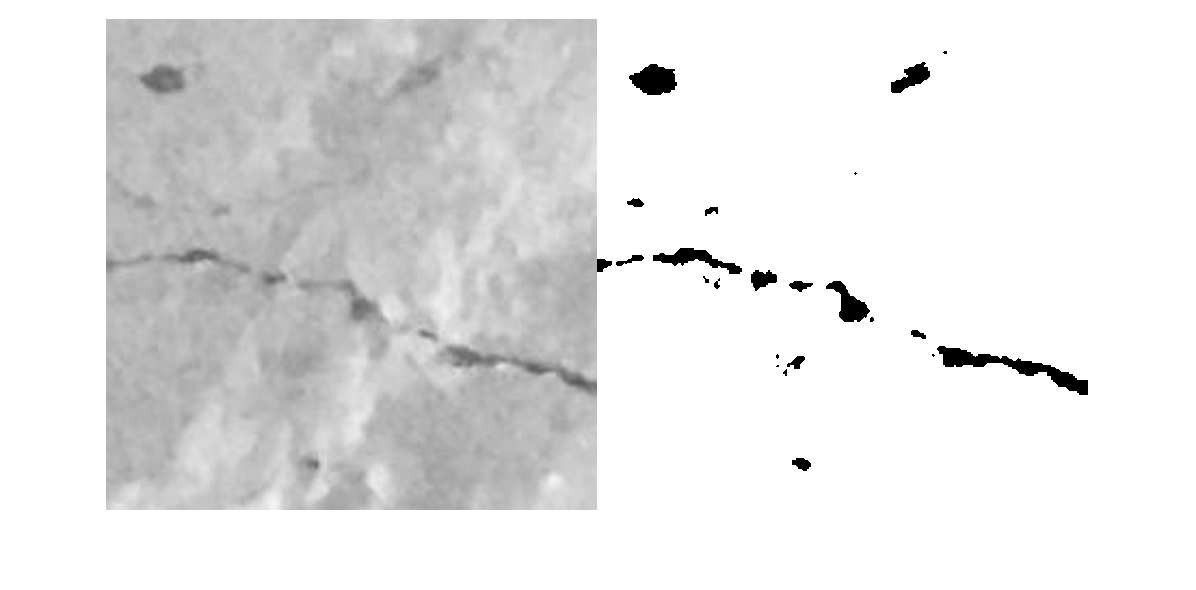

montage({img, BW})

graythresh(img)

ans = 0.7451

#### Adaptive threshold: 

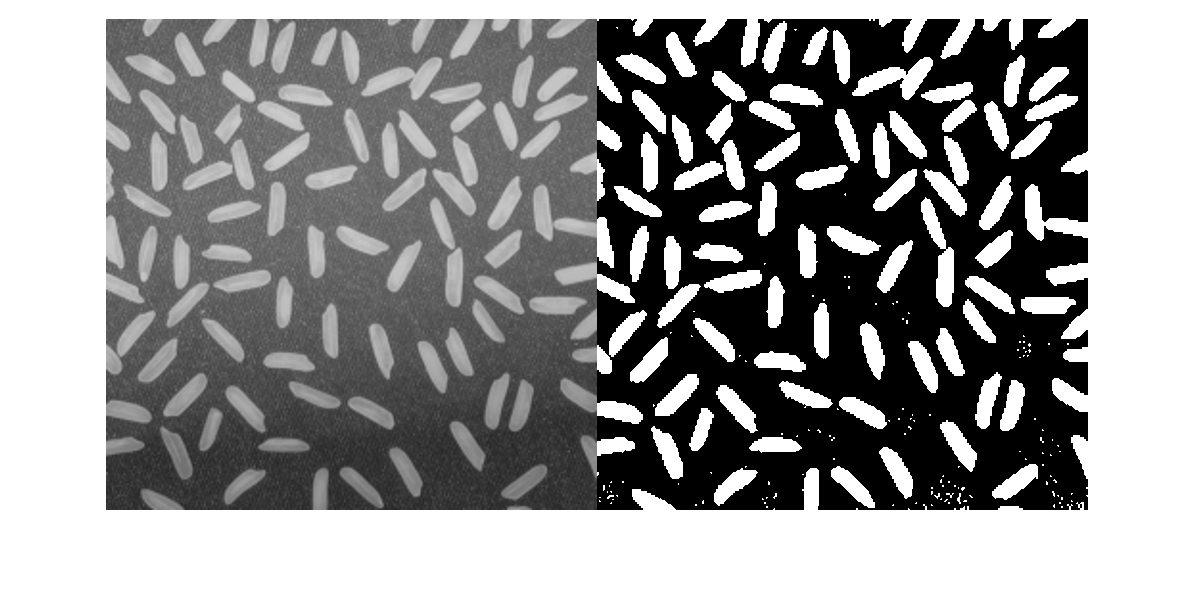

rice = imread("rice.png");
BW  = imbinarize(rice, "adaptive");

montage({rice, BW})

#### Multilevel Threshold : 

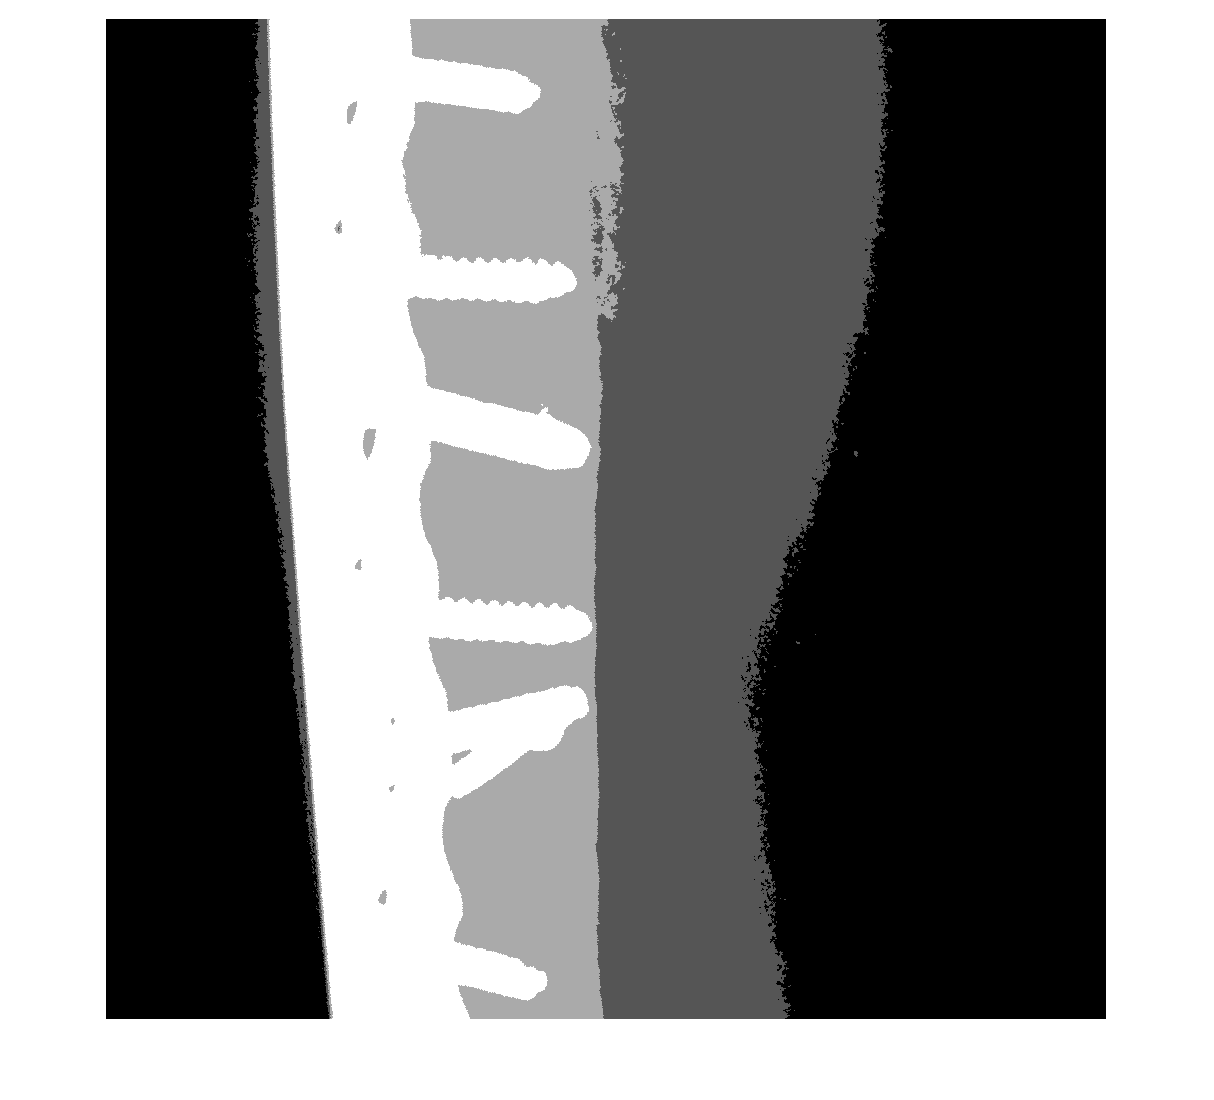

xray = imread("Data/MathWorks Images/armxray.png");

multithreh_val = multithresh(xray, 3);
labels = imquantize(xray, multithreh_val);
imshow(labels, [])

Sectioning only the bone :

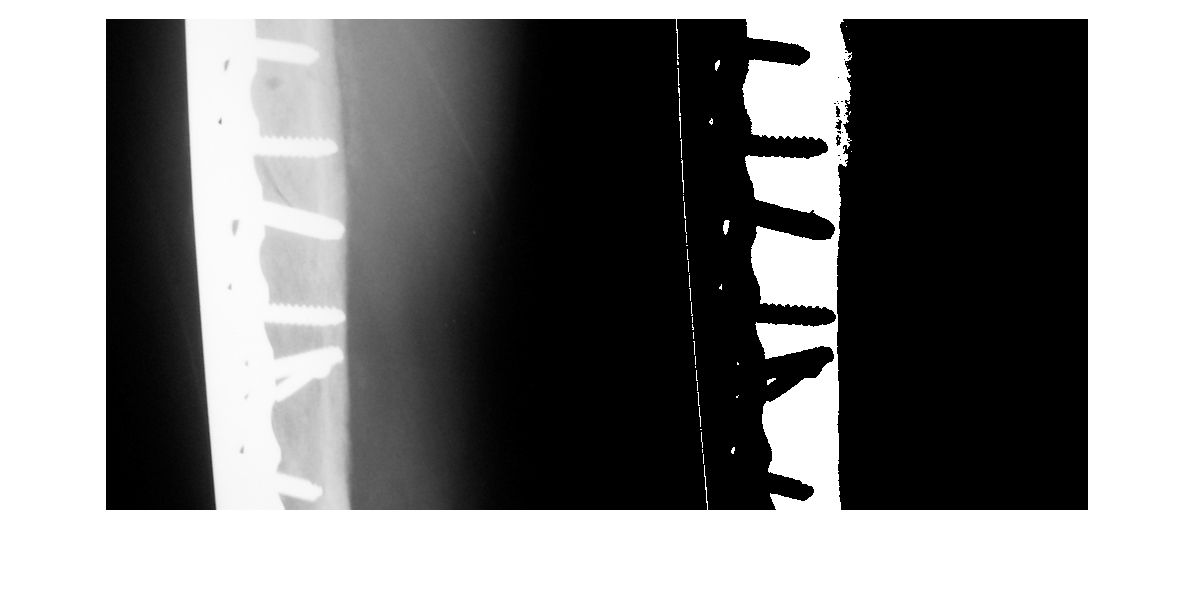

img_label3 = labels ==3;img_label3img_label3
montage({xray, img_label3})